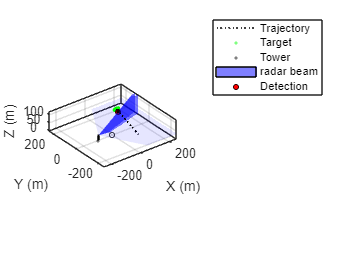

simulationDuration = 100;
scene = radarScenario('StopTime',simulationDuration);
tp = theaterPlot('XLimits',[-250 250],'YLimits',[-250 250],'ZLimits',[0 120]);
view(3);grid on;
timeOfArrival = [0  simulationDuration];
waypoints = [100 -100 10; 100 100 80];
trajectory = waypointTrajectory(waypoints,timeOfArrival);
target = platform(scene,'Trajectory',trajectory,'Dimensions', ...
    struct('Length',35,'Width',15,'Height',5.5,'OriginOffset',[0 0 0]));
trajPlotter = trajectoryPlotter(tp,'DisplayName','Trajectory','Color','k','LineWidth',1.2);
plotTrajectory(trajPlotter,{trajectory.Waypoints})
targetPlotter = platformPlotter(tp,'DisplayName','Target', ...
    'Marker','s','MarkerEdgeColor','g','MarkerSize',2);
plotPlatform(targetPlotter,target.Position, ...
    target.Dimensions,quaternion(target.Orientation,'rotvecd'))
hold on
plot3(tp.Parent,0,0,0,'Color','k','Marker','o','MarkerSize',4)
tower = platform(scene,'Position',[-100,0,0],'Dimensions', ...
    struct('Length',5,'Width',5,'Height',30,'OriginOffset',[0 0 -15]));
towerPlotter = platformPlotter(tp,'DisplayName','Tower','Marker','s','MarkerSize',2);
plotPlatform(towerPlotter,tower.Position,tower.Dimensions,quaternion(tower.Orientation,'rotvecd'))
radar = radarDataGenerator(1,'DetectionMode','Monostatic', ...
    'UpdateRate',5, ...
    'MountingLocation',[0, 0, 30], ...
    'FieldOfView',[4, 30],...
    'MechanicalAzimuthLimits',[-60 60], ...
    'MechanicalElevationLimits',[0 0], ...
    'HasElevation',true, ...
    'RangeResolution',200, ...
    'AzimuthResolution',20, ...
    'ElevationResolution',20);
tower.Sensors = radar;
radarPlotter = coveragePlotter(tp,'Color','b','DisplayName','radar beam');
plotCoverage(radarPlotter,coverageConfig(scene))
detPlotter = detectionPlotter(tp,'DisplayName','Detection','MarkerFaceColor','r','MarkerSize',4);
rng(2019) % for repeatable results
while advance(scene)
    % Plot target.
    plotPlatform(targetPlotter,target.Position, ...
        target.Dimensions,quaternion(target.Orientation,'rotvecd'))

    % Plot sensor coverage.
    plotCoverage(radarPlotter,coverageConfig(scene))

    % Extract target pose from the view of the tower and use the extracted
    % pose to generate detections.
    poseInTower = targetPoses(tower);
    [detections, numDets] = radar(poseInTower,scene.SimulationTime);
    detPos = zeros(numDets,3);
    detNoise = zeros(3,3,numDets);

    % Obtain detection pose relative to the scenario frame. Also, obtain
    % the covariance of the detection.
    for i=1:numDets
        a = detections;
        detPos(i,:) = tower.Trajectory.Position + detections{i}.Measurement';
        detNoise(:,:,i) = detections{i}.MeasurementNoise;
    end

    % Plot any generated detections with the covariance ellipses.
    if ~isempty(detPos)
        plotDetection(detPlotter,detPos,detNoise)
    end
end